# Homework 2

## Question 1

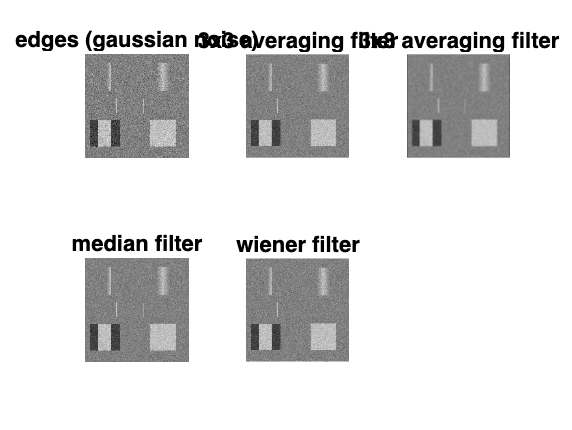

% loading images
edges = load("Edges.mat").Edges;
edges_g = load("Edges_gnoise.mat").Edges_gnoise;
edges_sp = load("Edges_spnoise.mat").Edges_spnoise;

% creating filters
avg3 = ones(3)/9;
avg9 = ones(9)/81;

% creating filtered images from gaussian noise
eg_avg3 = imfilter(edges_g,avg3);
eg_avg9 = imfilter(edges_g,avg9);
eg_med = medfilt2(edges_g);
eg_w = wiener2(edges_g, [3 3], 0.005);


% plotting filtered gaussian noise images
figure
subplot(2,3,1)
imshow(edges_g)
title("edges (gaussian noise)")
subplot(2,3,2)
imshow(eg_avg3)
title("3x3 averaging filter")
subplot(2,3,3)
imshow(eg_avg9)
title("3x3 averaging filter")
subplot(2,3,4)
imshow(eg_med)
title("median filter")
subplot(2,3,5)
imshow(eg_w)
title("wiener filter")

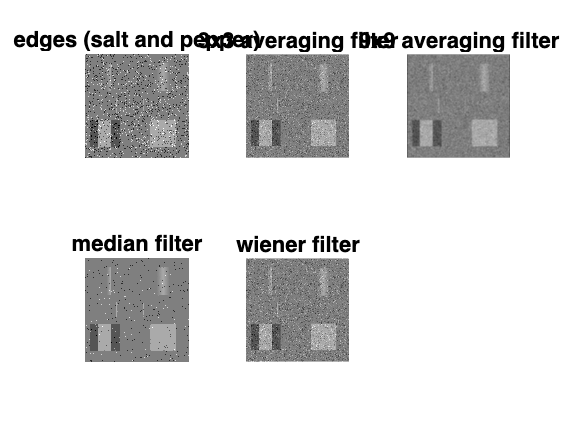


% filtering salt and pepper images
esp_avg3 = imfilter(edges_sp,avg3);
esp_avg9 = imfilter(edges_sp,avg9);
esp_med = medfilt2(edges_sp);
esp_w = wiener2(edges_sp, [3 3], 0.03);

% plotting filtered salt and pepper images
figure
subplot(2,3,1)
imshow(edges_sp)
title("edges (salt and pepper)")
subplot(2,3,2)
imshow(esp_avg3)
title("3x3 averaging filter")
subplot(2,3,3)
imshow(esp_avg9)
title("9x9 averaging filter")
subplot(2,3,4)
imshow(esp_med)
title("median filter")
subplot(2,3,5)
imshow(esp_w)
title("wiener filter")

a. 9x9 averaging filter

b. 3x3 averaging filter is the best at reducing noise overall.

c. The Wiener filter is the best at smoothing out noise without blurring the edges too much.

d. The median filter is the best at reducing salt and pepper noise.

e. This filter is a linear filter that simultaneously reduces noise and preserves edges. It takes the added noise to the image as input and reduces it to preserve the relevant signals. It minimizes the MSE between the output and input image preserve as much of the original image as possible.

f. The edges are more well-defined with the Wiener filter than with traditional averaging filters.

## Question 2

gauss_img = abs(50 + randn(500)*30); % creating image with gaussian noise
avg5 = ones(5)/25; % creating 5x5 avg filter

gauss_img_mean = mean2(gauss_img) % mean of original image

gauss_img_mean = 51.1689

gauss_img_stdev = std2(gauss_img) % standard deviation of original image

gauss_img_stdev = 27.8968


gfilt_avg = imfilter(gauss_img, avg5); % original image through 5x5 kernel
gauss_img_filt1_stdev = std2(gfilt_avg) % sd of filtered image

gauss_img_filt1_stdev = 5.9446

expected_filtered_stdev = gauss_img_stdev/5 % expected sd of filtered image

expected_filtered_stdev = 5.5794

gfilt_avg2 = imfilter(gfilt_avg, avg5); % filtered image through 5x5 kernel
gauss_img_filt2_stdev = std2(gfilt_avg2) % sd of new filtered image

gauss_img_filt2_stdev = 4.7515

gfilt_med = medfilt2(gauss_img, [5 5]); % original image through median filter
gauss_img_medfilt_stdev = std2(gfilt_med) % sd of median filtered image

gauss_img_medfilt_stdev = 7.8572

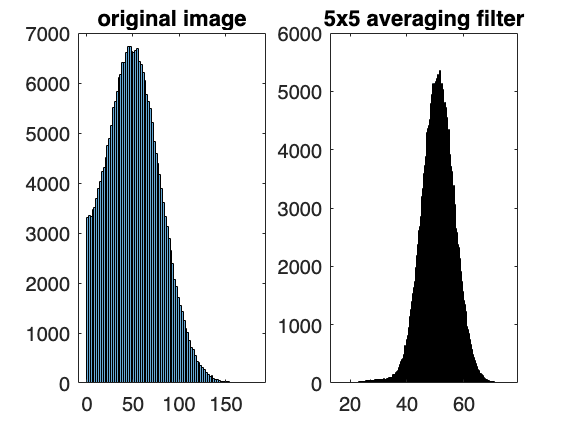


% histogram of original image and filtered through 5x5 kernel
figure
subplot(1,2,1)
histogram(gauss_img)
title("original image")
subplot(1,2,2)
histogram(gfilt_avg)
title("5x5 averaging filter")

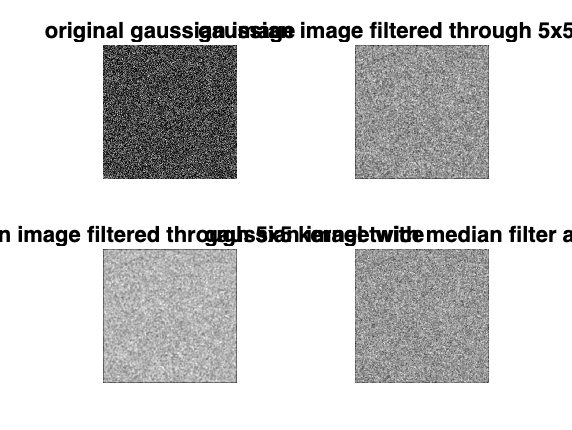


% displaying images
figure
subplot(2,2,1)
imshow(gauss_img, [])
title("original gaussian image")
subplot(2,2,2)
imshow(gfilt_avg, [])
title("gaussian image filtered through 5x5 kernel")
subplot(2,2,3)
imshow(gfilt_avg2, [])
title("gaussian image filtered through 5x5 kernel twice")
subplot(2,2,4)
imshow(gfilt_med, [])
title("gaussian image with median filter applied")


% converting to 8-bit data
gauss_img_uint8 = uint8(gauss_img);
gauss_filt_uint8 = uint8(gfilt_avg);
% finding bounds of original and 8-bit data
[min_gauss_orig, max_gauss_orig] = bounds(gauss_img, "all") % bounds of original image

min_gauss_orig = 3.4190e-04

max_gauss_orig = 183.0357

[min_gfilt, maxgfilt] = bounds(gfilt_avg, "all") % bounds of filtered image

min_gfilt = 15.9373

maxgfilt = 76.0987

[min_gauss_orig_uint8, max_gauss_orig_uint8] = bounds(gauss_img_uint8, "all") % bounds of original image (8-bit)

min_gauss_orig_uint8 = uint8
0

max_gauss_orig_uint8 = uint8
183

[min_gfilt_uint8, max_filt_uint8] = bounds(gauss_filt_uint8, "all") % bounds of filtered image (8-bit)

min_gfilt_uint8 = uint8
16

max_filt_uint8 = uint8
76

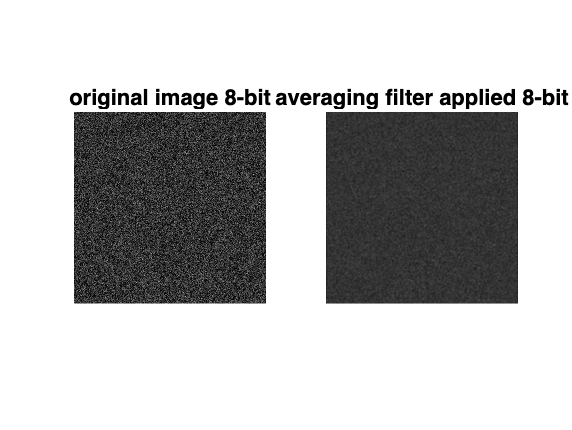


% displaying 8-bit data
figure
subplot(1,2,1)
imshow(gauss_img_uint8)
title("original image 8-bit")
subplot(1,2,2)
imshow(gauss_filt_uint8)
title("averaging filter applied 8-bit")

a. The standard deviation of the new image will be the standard deviation of the original image divided by 5, according to the formula from class. The expected standard deviation is very close to the standard deviation of the filtered image.

b. The new standard deviation is not the standard deviation of the image divided by 5, which goes against the theory in part a. This is because the image has already been through a filter, so filtering it again with the same kernel will be less effective.

c. Standard deviations of the original image and the median filtered image are given.

d. The standard deviation of the averaging filtered image is lower than the standard deviation of the median filtered image, which means that an averaging filter is better for Gaussian noise than a median filter.

e. The minimum and maximum values for the images and the same data in 8-bit is given. The 8-bit data found the floor of the values. The new images are also much darker.

## Question 3

% load image
edges_sp = load("Edges_spnoise.mat").Edges_spnoise;

% create median filter in shape of cross
cross = [0 0 1 0 0; 0 0 1 0 0; 1 1 1 1 1; 0 0 1 0 0; 0 0 1 0 0];

% median filtered image (cross shape)
edges_med_cross = ordfilt2(edges_sp,5,cross);
% median filtered image (medfilt)
edges_sp_med = medfilt2(edges_sp); % 

sd_edges = std2(edges_sp) % sd of original image

sd_edges = 8.8687e+03

sd_medcross_edges = std2(edges_med_cross) % sd of cross filtered image

sd_medcross_edges = 5.1526e+03

sd_medfilt_edges = std2(edges_sp_med) % sd of medfilt2 image

sd_medfilt_edges = 5.4471e+03

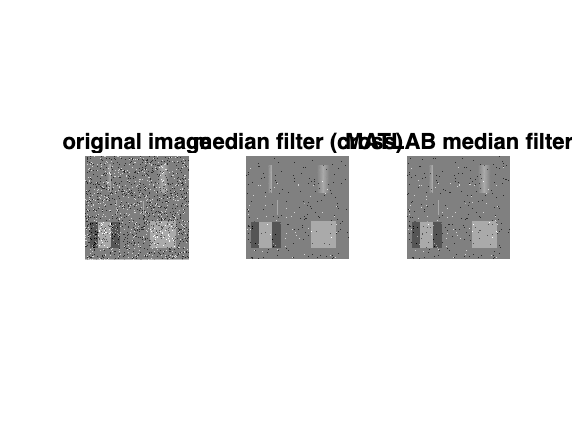


% displaying images
figure
subplot(1,3,1)
imshow(edges_sp, [])
title("original image")
subplot(1,3,2)
imshow(edges_med_cross, [])
title("median filter (cross)")
subplot(1,3,3)
imshow(edges_sp_med, [])
title("MATLAB median filter")

Quantitatively, the standard deviation of the image with the median filter in the shape of a cross was slightly lower than the median filter from MATLAB. Qualitatively, this is shown by the reduced amount of salt and pepper noise in the image with the cross filter applied than the regular median filter. Additionally, by inspection, we can see that the edges in the image are preserved to a greater degree by the cross filter than the MATLAB one.

## Question 4

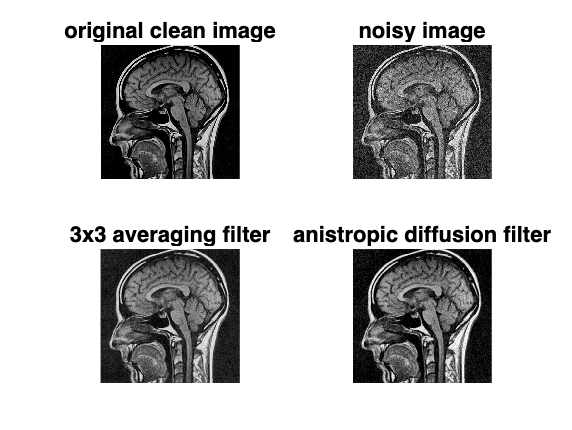

% load images
mri_noisy = imread("mri_brain_sagittal-noisy.tif");
mri_clean = imread("mri_brain_sagittal.tif");

avg3 = ones(3)/9; % creating averaging kernel
mri_avg3 = imfilter(mri_noisy,avg3); % image with averaging filter

% anisotropic diffusion filtered image
mri_diffuse = imdiffusefilt(mri_noisy,"NumberOfIterations",2, ...
    "Connectivity", "minimal", "GradientThreshold", [1000 1000]);

% testing params
% figure
% subplot(1,3,1)
% imshow(mri_clean, [])
% clim([50 300])
% subplot(1,3,2)
% imshow(imdiffusefilt(mri_noisy, "NumberOfIterations",3, ...
%     "Connectivity", "minimal", "GradientThreshold", gradThresh), [])
% subplot(1,3,3)
% imshow(imdiffusefilt(mri_noisy, "NumberOfIterations",3, ...
%     "Connectivity", "minimal", ...
%     "GradientThreshold", uint16([500 500 500]), ...
%     "ConductionMethod","exponential"), [])

% plot images
figure
subplot(2,2,1)
imshow(mri_clean, [])
clim([50 300])
title("original clean image")
subplot(2,2,2)
imshow(mri_noisy, [])
clim([0 300])
title("noisy image")
subplot(2,2,3)
imshow(mri_avg3, [])
clim([20 283])
title("3x3 averaging filter")
subplot(2,2,4)
imshow(mri_diffuse, [])
clim([40 260])
title("anistropic diffusion filter")

In order to obtain the optimal filter parameters, I first used imdiffuseest to estimate the optimal parameters for exponential and quadratic conduction methods. I found that exponential gave crisper edges than quadratic, so I opted to use that. The number of iterations I originally got was 3, which I reduced to 2 after checking a larger and smaller number of iterations. I also reduced the gradient threshold from the recommended roughly 9000-11000 for each iteration after testing larger and smaller thresholds. I changed one parameter at a time and compared it to the most optimal result I had at the time, then made changes to the optimal parameters if necessary.